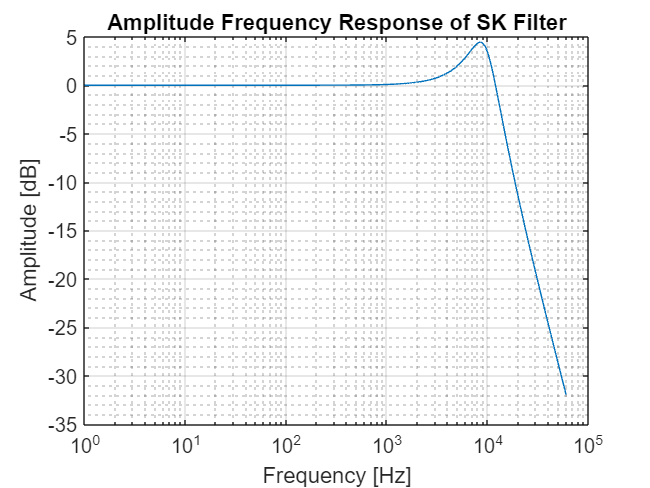

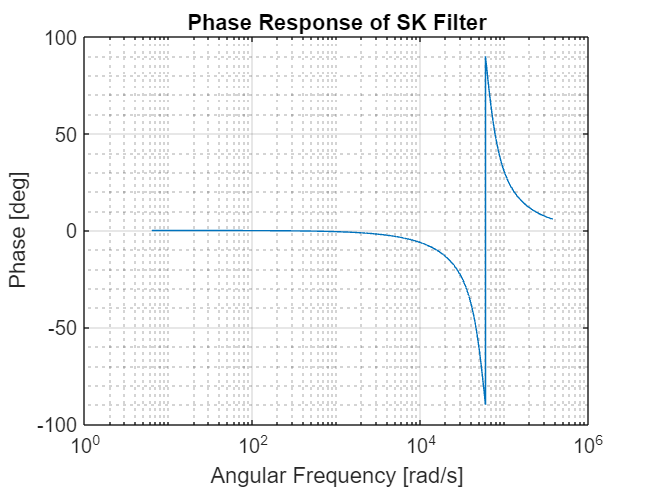

Q = 1.5811

f_c = 9.4396e+03

clc; clear, close all


[Q,f_c] = SallenKeyFR(1E-6,.1E-6,335)

function [Q,f_c] = SallenKeyFR(C1,C2,R)

% Calculate Q, f_c, w_c
Q = 0.5*sqrt(C1/C2);
f_c = 1/(R*sqrt(C1*C2));
w_c = 2*pi*f_c;

% Frequency Range
f = 0:1:60000;
w = 2*pi .* f;

% Frequency Response
Hw = w_c^2./(sqrt((w_c^2-w.^2).^2 + ((w_c.*w)/Q).^2));
log_Hw = 20*log10(Hw);

% Plot Frequency Response
figure(1);
semilogx(f,log_Hw)
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')
grid on; grid minor;
title('Amplitude Frequency Response of SK Filter')

% Phase Response
phase = -atand( (w_c.*w./Q) ./ (w_c^2-w.^2)) ;

% Plot Phase Response
figure(2);
semilogx(w,phase)
xlabel('Angular Frequency [rad/s]')
ylabel('Phase [deg]')
grid on; grid minor;
title('Phase Response of SK Filter')

end